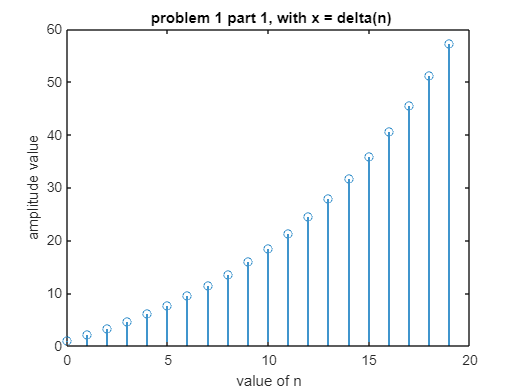

%problem on lab3 slide4
%x(n) = y(n) - 2.1y(n-1) + 1.1y(n-2)

a = [1, -2.1 1.1]; %coefficients
b = [1];
n = 0:1:19; %time range

%part 1
x1 = [1 zeros(1, 19)];
y1 = filter(b, a,x1);
stem(n, y1);
title(" problem 1 part 1, with x = delta(n)");
xlabel("value of n"); ylabel("amplitude value")

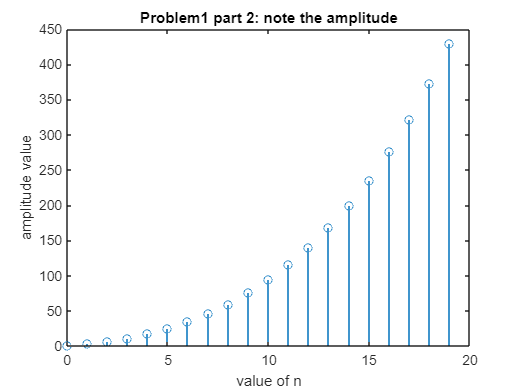


%part 2
x2 = [ones(1, 20)];
y2 = filter(b, a, x2);
stem(n, y2);
title("Problem1 part 2: note the amplitude");
xlabel("value of n"); ylabel("amplitude value")

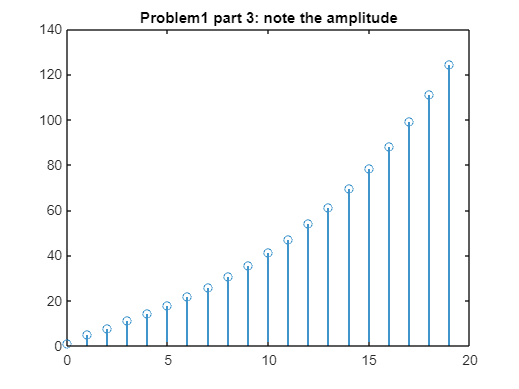


%part 3
x3 = [1 3 -2 1 -1 zeros(1, 15)];
y3 = filter(b, a, x3);
stem(n,y3);
title("Problem1 part 3: note the amplitude");

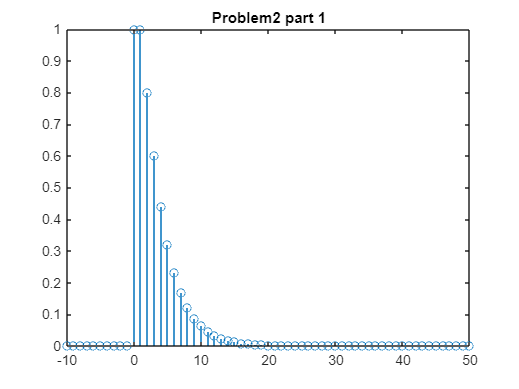


%note that since we only have a single input signal, b remains 1

%problem from lab3 slide6
%y(n) - y(n-1) + 0.8y(n-2) = x(n)
b2 = [1];
a2 = [1 -1 0.2];
%note that the n ranges here will change, but the x's uses will not from
%problem 1

n2 = -10:1:50; %this is the requested range.

xb1 = impseq(0, -10, 50);
yb1 = filter(b2, a2, xb1); %note x1 was the impulse reponse
stem(n2, yb1);
title("Problem2 part 1");

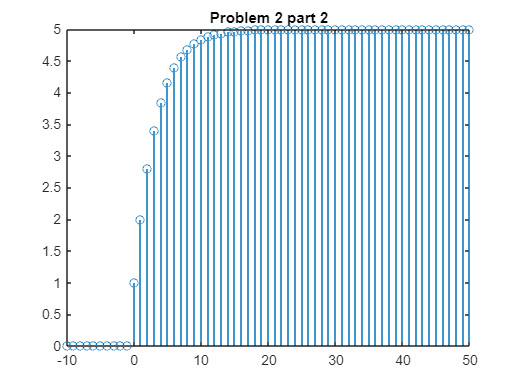


xb2 = stepseq(0, -10, 50);
yb2 = filter(b2, a2, xb2);
stem(n2, yb2);
title("Problem 2 part 2");

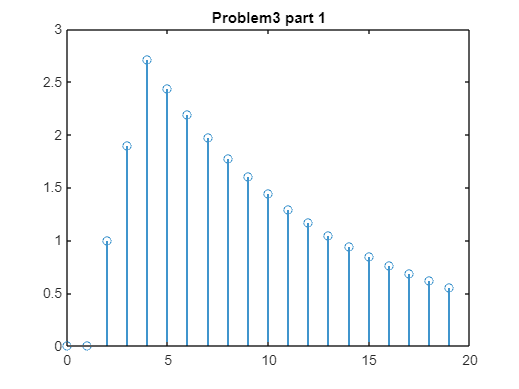


%problem from lab 3 slide 5
a3 = [1 -0.9];
b3 = [1];
n3 = 0:1:19; %time range

%we first need to display the rectangular pulse n1 = 3, lp =3, k=1, n=20
recp = [0 0 1 1 1 zeros(1, 15)];
y3a = filter(b3, a3, recp);
stem(n3, y3a);
title("Problem3 part 1");

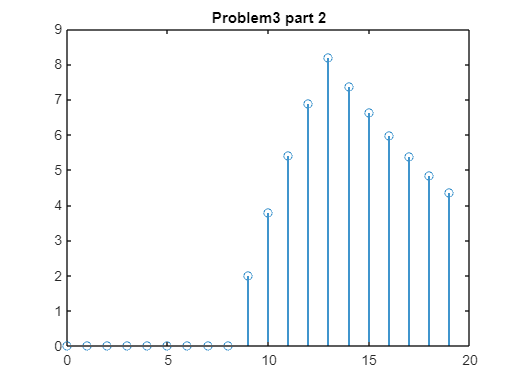


%and then display another pulse n1 = 10, lp = 5, k=2, n = 20
pulse = [zeros(1,9) 2 2 2 2 2 zeros(1, 6)];
y3b = filter(b3, a3, pulse);
stem(n3, y3b);
title("Problem3 part 2");


%now we need to test for linearity....
y3 = sigadd(y3b, n3, y3a, n3);

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19


y1 =          0         0         0         0         0         0         0         0         0    2.0000    3.8000    5.4200    6.8780    8.1902    7.3712    6.6341    5.9707    5.3736    4.8362    4.3526


y2 =          0         0    1.0000    1.9000    2.7100    2.4390    2.1951    1.9756    1.7780    1.6002    1.4402    1.2962    1.1666    1.0499    0.9449    0.8504    0.7654    0.6888    0.6200    0.5580


y =          0         0    1.0000    1.9000    2.7100    2.4390    2.1951    1.9756    1.7780    3.6002    5.2402    6.7162    8.0446    9.2401    8.3161    7.4845    6.7360    6.0624    5.4562    4.9106


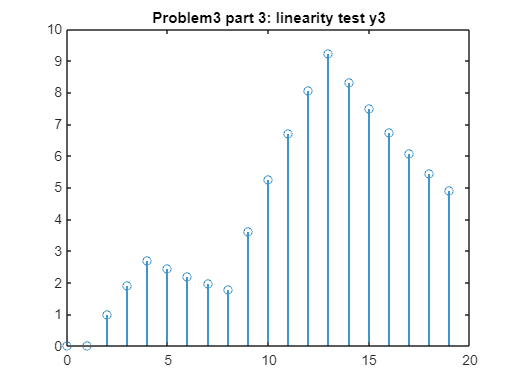

stem(n3, y3); %so this displays both part a and part b together given the values of x.
title("Problem3 part 3: linearity test y3");

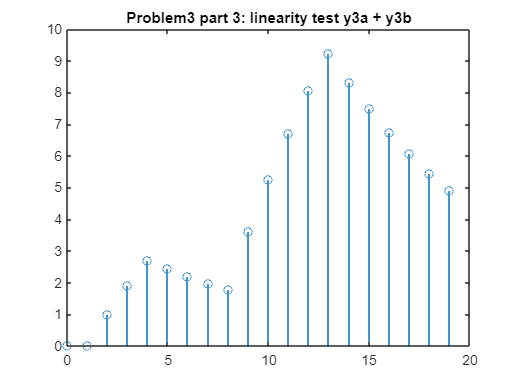

stem(n3, y3a + y3b);
title("Problem3 part 3: linearity test y3a + y3b");

%note that these two are the same. this means that the system is linear.


%Digital Oscillator Design
%lab 3 slide 7

